# Reduced Order Model of a Permanent Magnet Synchronous Motor (PMSM)

Set up the environement

clear
clc
addpath(genpath(cd));

## 1. Import and Visualize the Data of interest

We have a big .csv file with measurement data from different experiments. 

The data is used from: https://www.kaggle.com/wkirgsn/electric-motor-temperature 

tt=readtimetable("pmsm_temperature_data_new.csv",SampleRate=2);

The file contains two data sets, each with ambient temperature, coolant temperature, pressure and maximum blade displacement signals

head(tt)

     Time      ambient     coolant      u_d        u_q      motor_speed     torque      i_d        i_q         pm       stator_yoke    stator_tooth    stator_winding    profile_id
    _______    ________    _______    _______    _______    ___________    ________    ______    ________    _______    ___________    ____________    ______________    __________

    0 sec      -0.75214    -1.1184    0.32794    -1.2979      -1.2224      -0.25018    1.0296    -0.24586    -2.5221      -1.8314        -2.0661  

**The following measurements are our inputs:**

- Ambient Temperature

- Coolant Temperature

- Motor Voltage (dq-Frame)++

- Motor Current (dq-Frame) 

**We want to predict the following values:**

- Permanent Magnet Temperature

- Stator Yoke Temperature

- Stator Tooth Temperature

- Stator Winding Temperature

### 1.1 Visualize an experiment

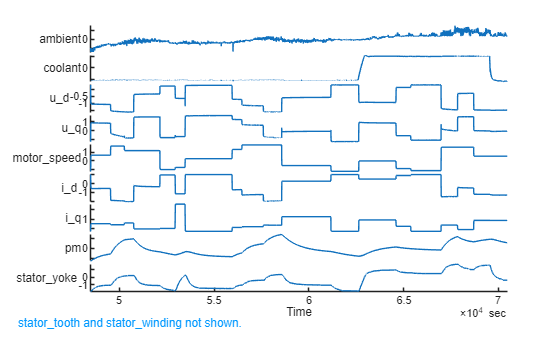

stackedplot(tt((tt.profile_id==20),[1:5,7:12]));

## 2. Load the Data and Features

Features are derived from the csv data and saved as the mat file. The file generateFeaturesPMSM walks through the process of feature generation

clear;
load Data/pmsm_temperature_data_large.mat;

## **3. Prepare Training Data**

Remove a data set for Testing in Simulink in section 7, which wont be used for training

testid = 57;
testSet = timetables{testid};
timetables(testid) = [];

## 4. Launch the Reduced Order Modeler app

Use the `reducedOrderModeler` command with a data1 input argument to launch the reduced order modeler app.

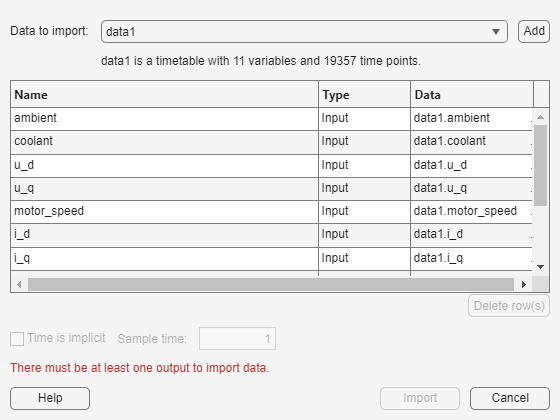

reducedOrderModeler(data1);

- The App opens with an import dialog to configure the data being imported.

- The dialog shows the variables in the imported timetable. Set the `ambient, cooling, u_d, u_q, motor_speed, i_d and i_q` as inputs and `pm, stator_yoke, stator_tooth and stator_winding` as an output.

- Click **Import** to import the data into the app.

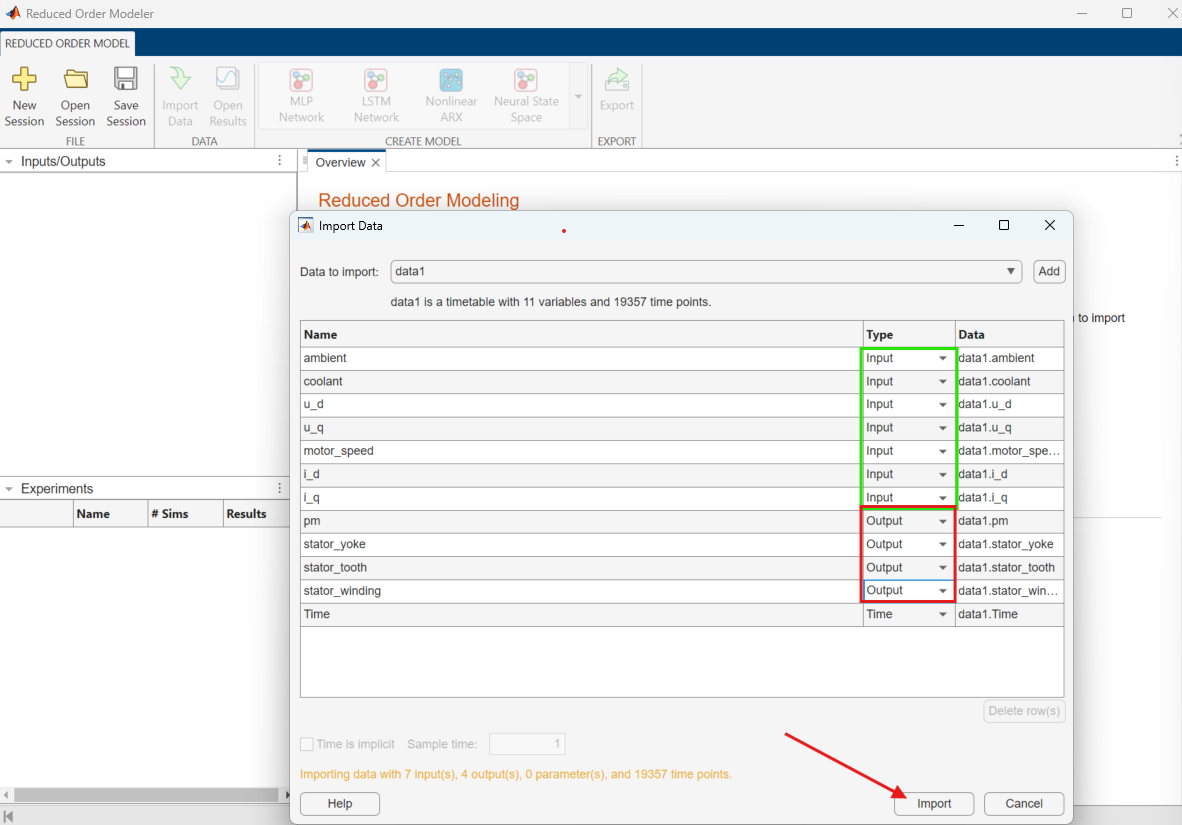

The imported data appears in the Experiments pane. 

In the reduced order modeler click **Import Data** to import all the profiles saved in the timetables cell.

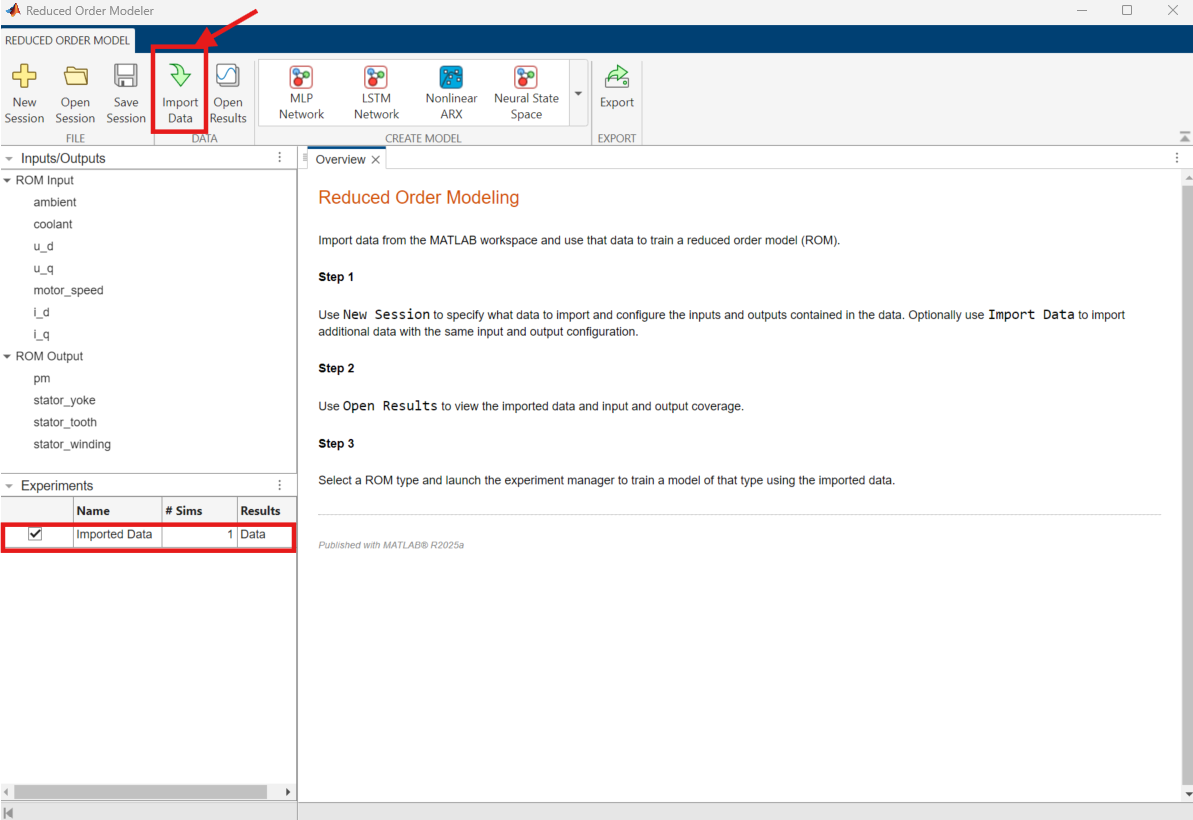

The import dialog is launched with the input/output ports configured and fixed and the **Data to import** drop down enabled to select data from the MATLAB workspace to import. In the drop down select timetables and click **Add**. After clicking Add the Import dialog should look like the image below

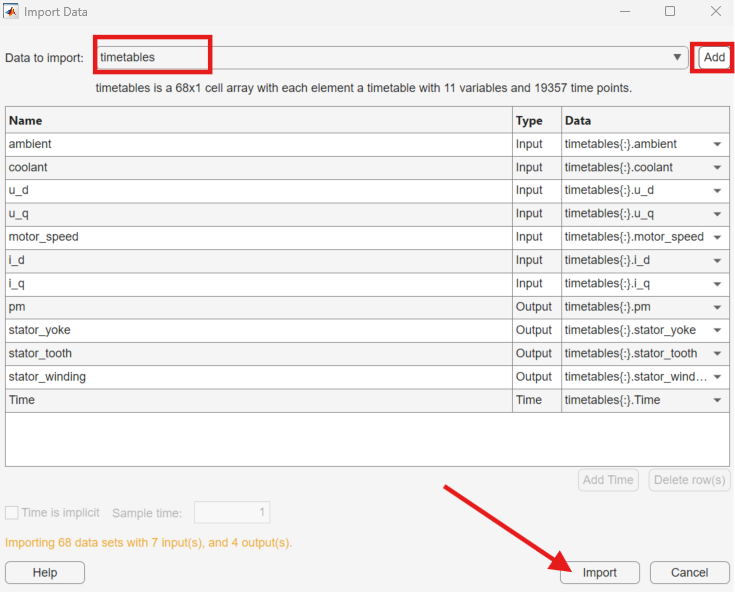

The imported data is assigned to the input/output ports and can be reassigned as needed. For this example no reassignment is needed.

In this example the data is imported in timetable format, data in numeric matrix format can also be imported. For more information on importing data, see the [**Options to Import Time-Domain Data as ROM Inputs and Outputs**](https://www.mathworks.com/matlabcentral/mlc-downloads/downloads/0cee96ac-b9e3-4632-9809-a7fd7d78d2b0/1742562087/previews/doc/examples/html/turbineblade_data_example.html) section at the end of this example.

### 4.1 View the Imported Data

Click **Open Results** in the reduced order modeler app to view the imported data.

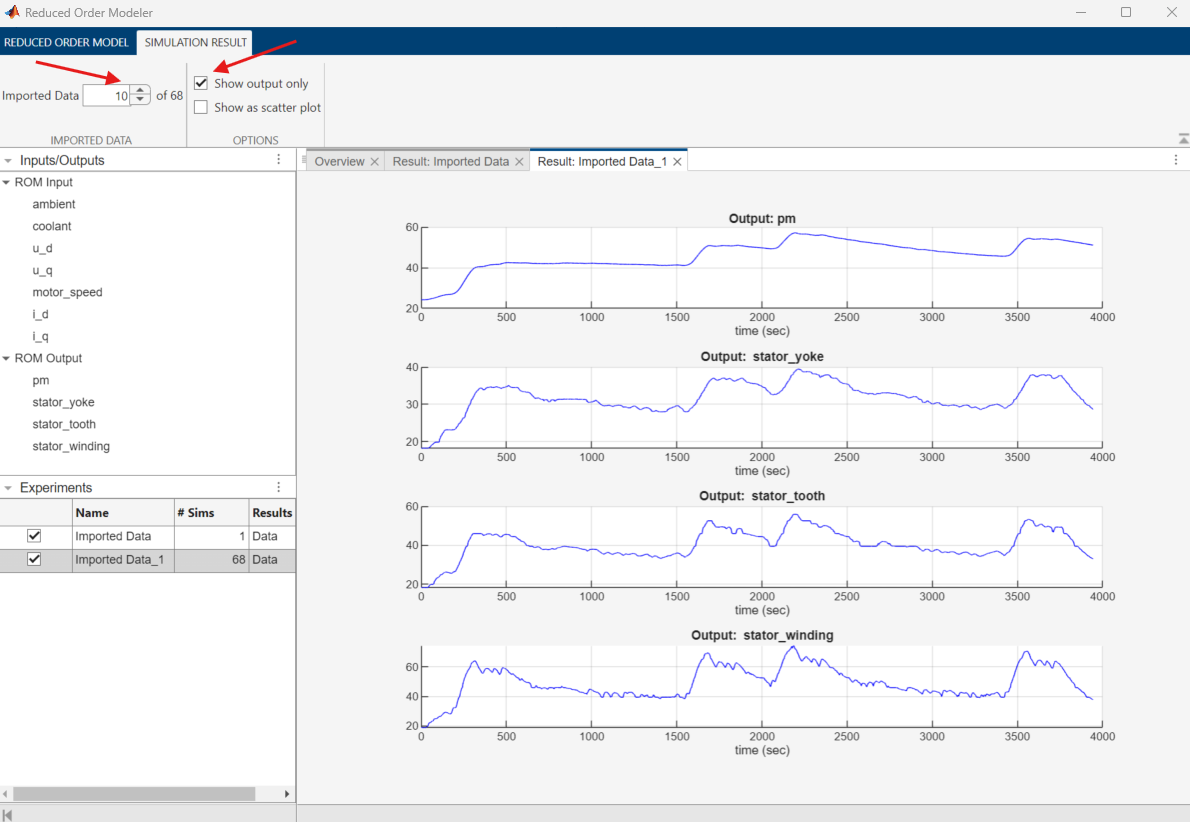

## 5. Create an LSTM Model

You can use the **Create Model** section on the **Reduced Order Model** tab to create a ROM.

Create an LSTM model to capture the system dynamics from inputs to outputs.

On the **Reduced Order Model** tab, in the **Create Model** gallery, click **LSTM** and select `Imported_Data1` to export. Doing so launches the Experiment Manager app. 

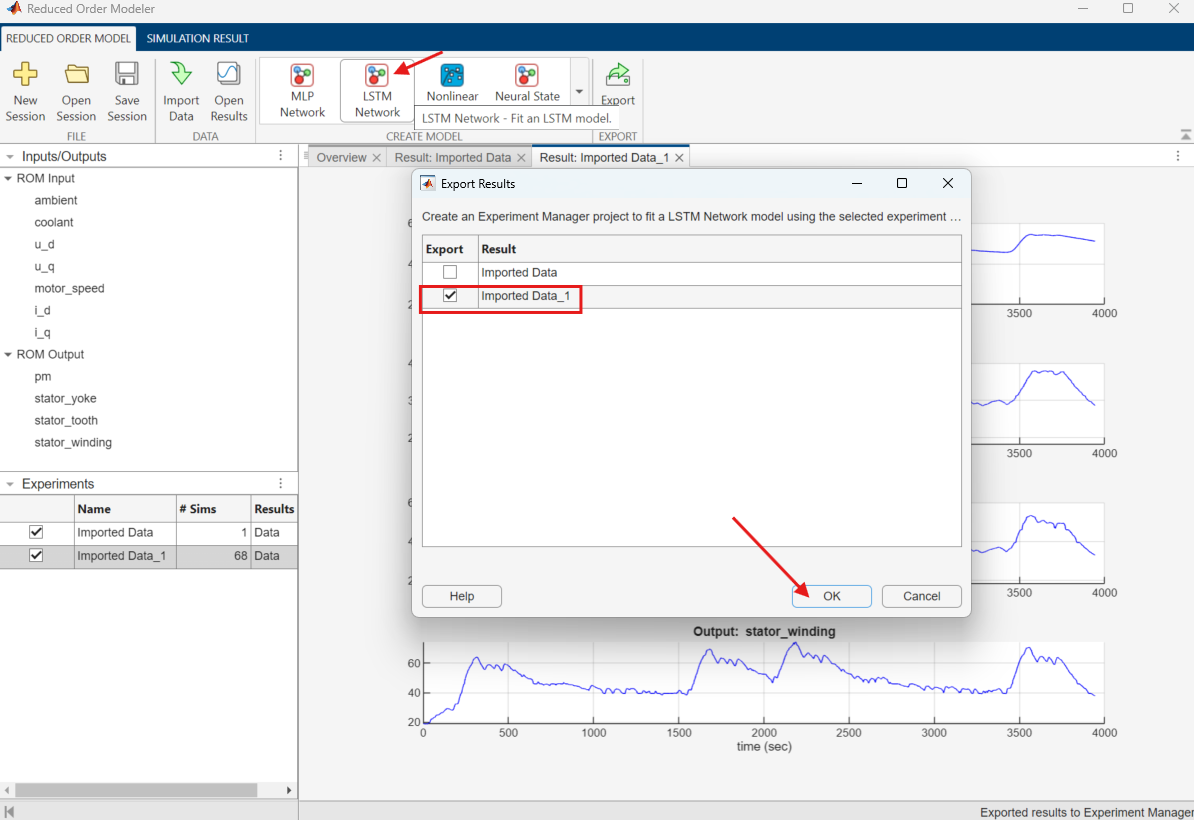

In the dialog box, select `New Project` and choose a suitable name and "**\ROM of a PMSM Motor\ROM_PMSM_ExperimentManager\**" folder location. 

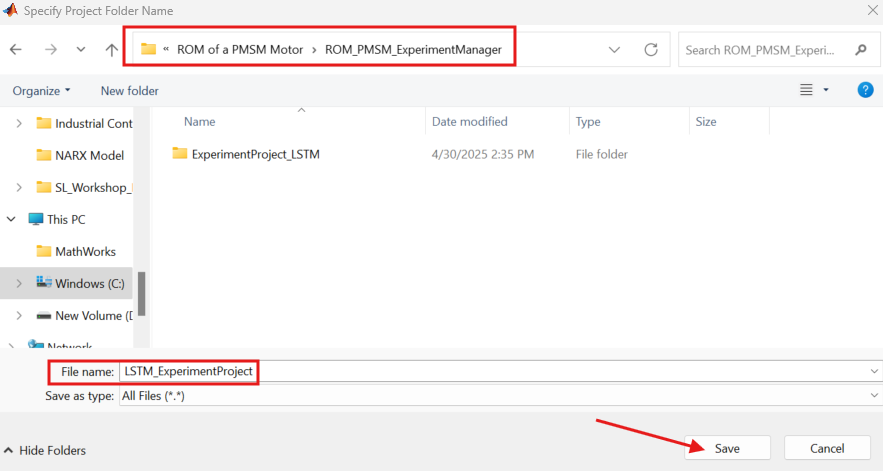

Experiment Manager creates an experiment to train an LSTM model using the collected data. 

Experiment manager sweeps over different hyperparameters to train different models and find the models that work best. Set the hyperparameters as follows:

- Set `SampleRate` to [0.5] — The sample rate of the LSTM model.

- Set `HiddenSize` to [20 80] — The number of hidden units to use in an LSTM layer.

- Set `InitialLearnRate` to [1e-5] — Initial learning rate used for training.

- Set `NumLayers` to [1 2] — The number of LSTM layers to use in an LSTM model.

In addition to the hyperparameters, you can also edit the function used to train the LSTM model. To open the training function, in the **Training Function** section, click **Edit**. This opens the training function. For this example, use the default training options.

Train the different models. To train the models in parallel, on the **Experiment Manager** tab, in the **Execution** section, set **Mode** to **Simultaneous**, and click **Run** .

Each trained model is shown as a row in the experiment results table. The value of the hyper parameters for each model are shown along with model performance metrics.

- **TrainingLoss** is the mean-squared error of the trained model, computed using outputs from simulations of the original training data signals. The training data signals were used to train the model.

- **TestLoss** is the mean-squared error of the trained model, computed using outputs from simulations for the original test data signals. The test data signals were not used to train the model.

Sort the trained models by **TestLoss** in ascending order by clicking the **TestLoss** column header.

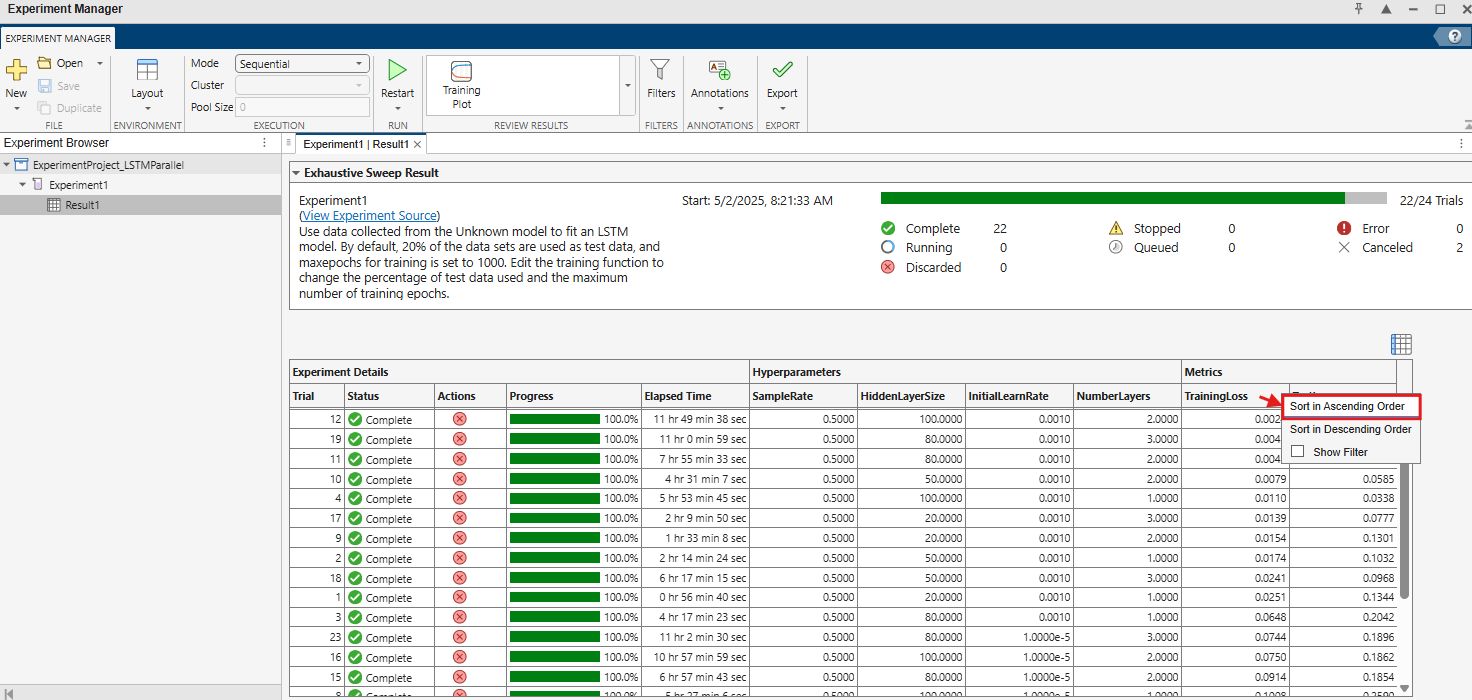

Models with low **TestLoss** and low **TrainingLoss** are good potential models. To export a selected model to the MATLAB workspace, right-click the corresponding row. Given the randomness in the experiment design for collecting data (random pulse sequences for ambient temperature, cooling temperature , and pressure), the exact model performance can vary.

### 5.1 Export the selected ROM model

Follow the section below and uncomment the code if you are using your own LSTM model.

To export a selected model to the MATLAB workspace, right-click the corresponding row. Given the randomness in the experiment design for collecting data and LSTM initialization, exact model performance may vary.

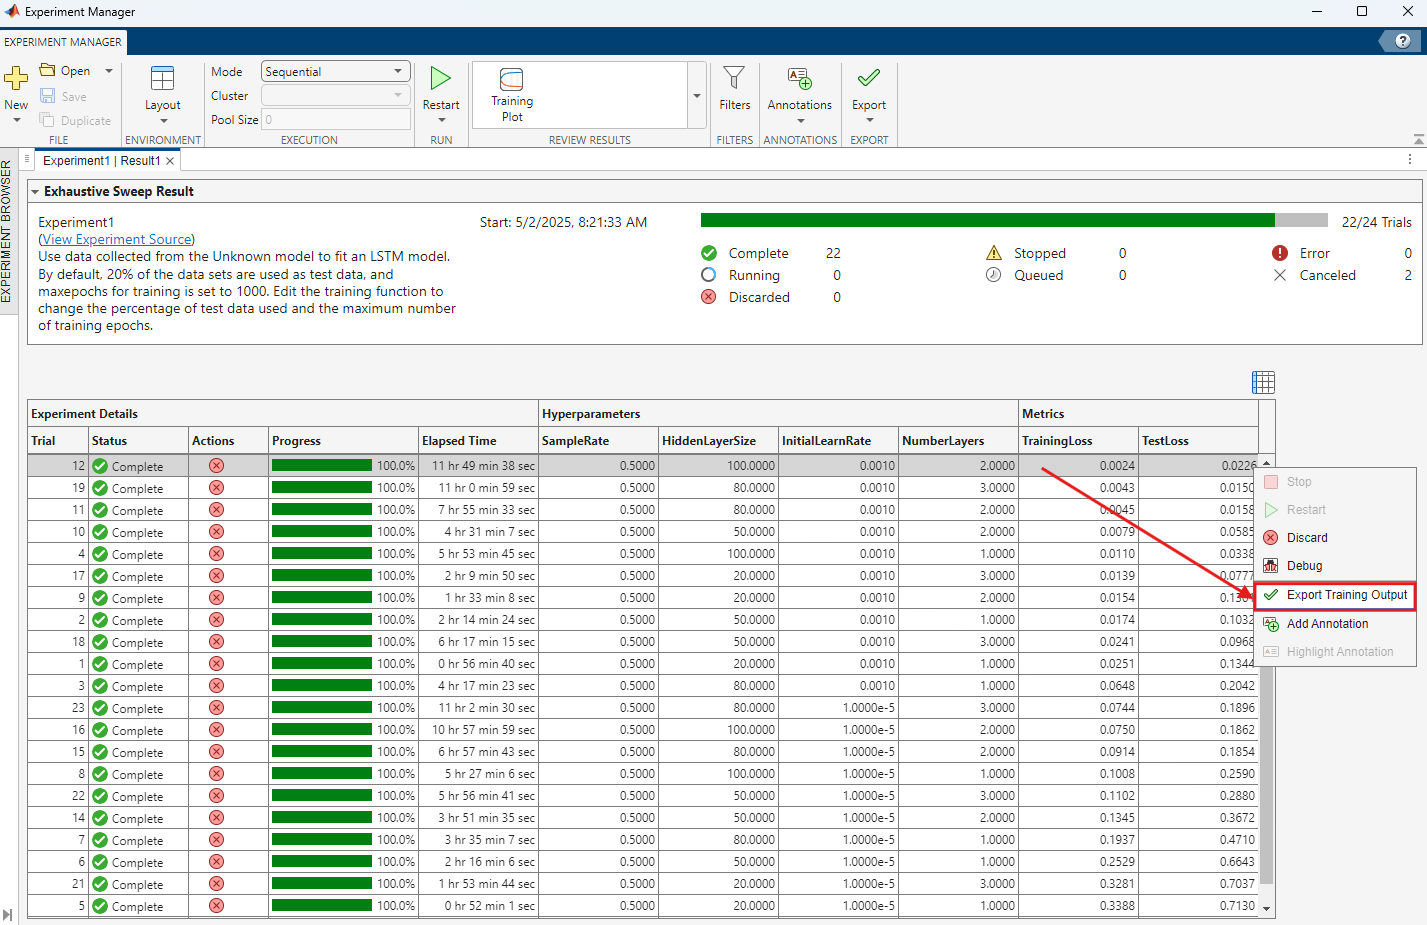

Provide your name to the training output model, example is shown below:

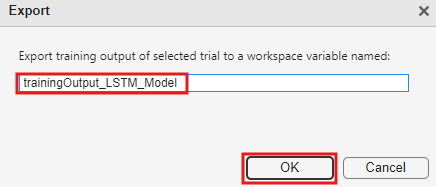

The model should now in the MATLAB workspace. You can check the model parameters by calling the model name in the command window as shown below

% trainingOutput_LSTM_Model

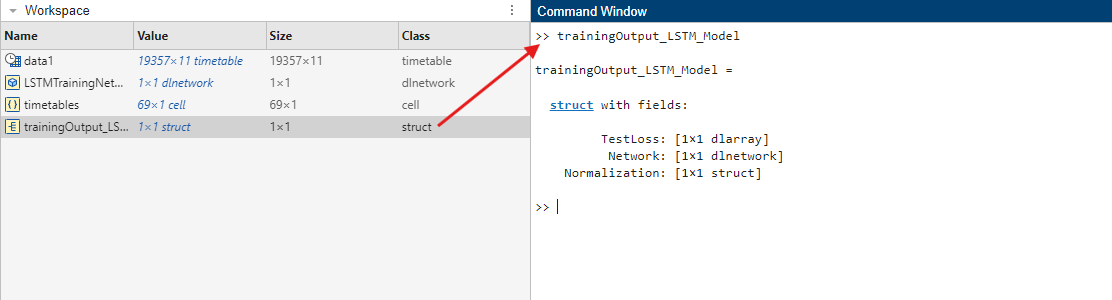

Save your trained and exported LSTM model in a mat file using the command below. Replace "trainingOutput_LSTM_Model" with the name of your exported model

% trainingOutput_LSTM_Network = trainingOutput_LSTM_Model.Network;
% save("My_LSTM_Model.mat","trainingOutput_LSTM_Model","trainingOutput_LSTM_Network")

This should create a new mat file in the file browser

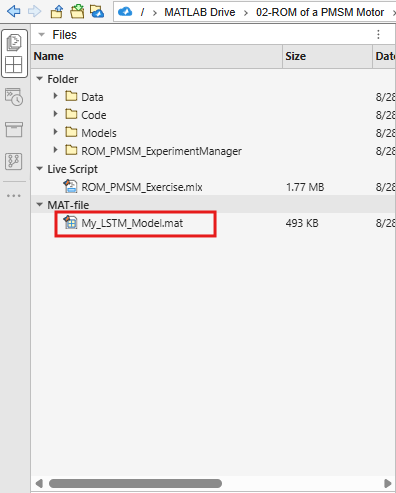

## 6. Create a Neural State-Space Model

Now create an NSS model to capture the system dynamics from inputs to outputs.

On the **Reduced Order Model** tab, in the **Create Model** gallery, click **Neural State Space** and select both sets of experiment results to export. Doing so launches the Experiment Manager app. In the dialog box, select `Existing Project` and choose the previously saved experiment manager project that was used for training the LSTM model. Experiment Manager creates an experiment to train a discrete-time neural state-space model using the collected data and adds it to the project.

Experiment manager sweeps over different hyperparameters to train different models and find models that work best. Set the NSS hyperparameters as follows:

- Set `NumberInputLags` to [0 1] — Number of lags for input signals.

- Set `NumberOutputLags` to [0 1 2] — Number of lags for output signals.

- Set `NumberLayers` to [2 3] — The number of layers to use in the multi-layer perceptron used in the NSS model.

- Set `NumberUnits` to [16 32 64] — The number of units to use in each layer.

- Set `SampleRate` to [0.5] — The sample rate of the discrete neural state-space model.

For a variable x(k), the number of lags specifies what lagged versions of the variable to use in the model, for example, [x(k) x(k-1) ...]. Lagged variables are added to the states of the NSS model.

In addition to the hyperparameters, you can also edit the function used to train the NSS model. To open the training function, in the **Training Function** section, click **Edit** . This opens the training function, where you can change additional settings, such as maximum number of epochs to use during training or the network initialization options. For this example, use the default training options.

Train the different models. To train the models in parallel, on the **Experiment Manager** tab, in the **Execution** section, set **Mode** to **Simultaneous**, and click **Run**.

Each trained model is shown as a row in the experiment results table. The value of the hyper parameters for each model are shown along with model performance metrics.

- **Loss** is the mean-absolute error minimized during training. The training data is split into mini batches of 20 data points each and the the mean-absolute error is the error for all batches.

- **TrainingMSE** is the mean-squared error of the trained model, computed using outputs from simulations of the original training data signals. The training data signals were used to train the model.

- **TestMSE** is the mean-squared error of the trained model, computed using outputs from simulations for the original test data signals. The test data signals were not used to train the model.

Sort the trained models by **TestMSE** in ascending order by clicking the **TestMSE** column header.View the "Test Data Plot" to visualize how the model performs compared to the validation data and select the best performing model.

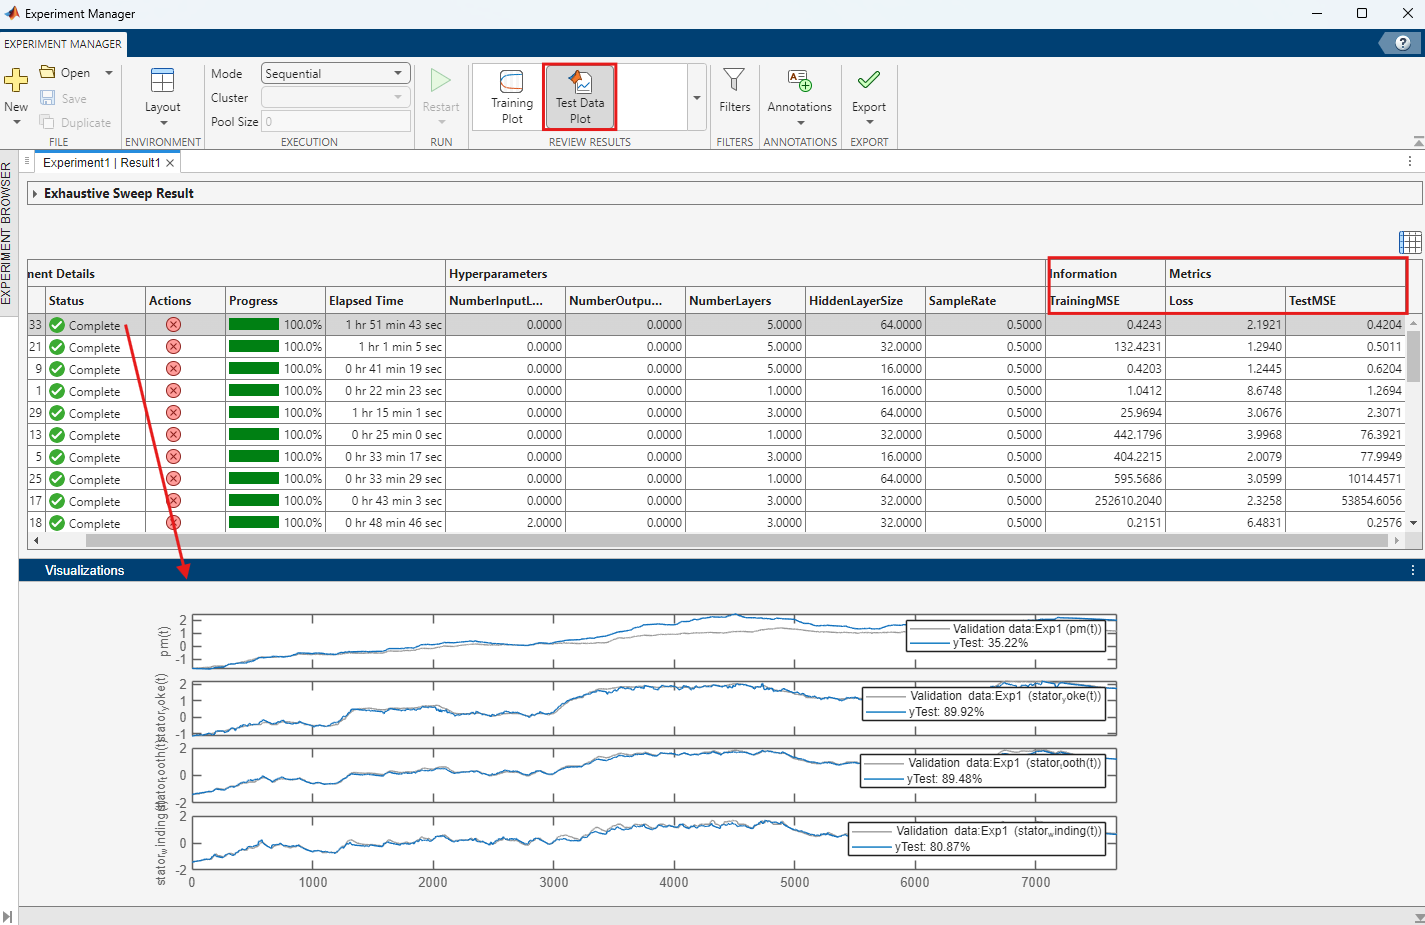

Models with low **TestMSE** , comparable **TrainingMSE** , and low **Loss** are good potential models. To export a selected model to the MATLAB workspace, right-click the corresponding row. Given the randomness in the experiment design for collecting data and NSS initialization, exact model performance may vary.

## 7. Use the Trained Reduced Order Models in Simulink

Once you export the trained models to MATLAB workspace, you can use the exported models in a Simulink model and compare the results to the original data. The `ValidateROM_PMSM.slx` model includes blocks to implement the trained LSTM model and the original data.

Open the Simulink model.

load_system("ValidateROM_PMSM");
open_system("ValidateROM_PMSM");

Uncomment the LSTM blocks to add your own custom trained LSTM network and test it with the Validation model

Replace the existing LSTM Model with the model you have exported to test your model peformance

- Double click on the LSTM Model block located at the top level of "ValidateROM_PMSM".

- Browse the new mat file you have created with your LSTM model as shown below:

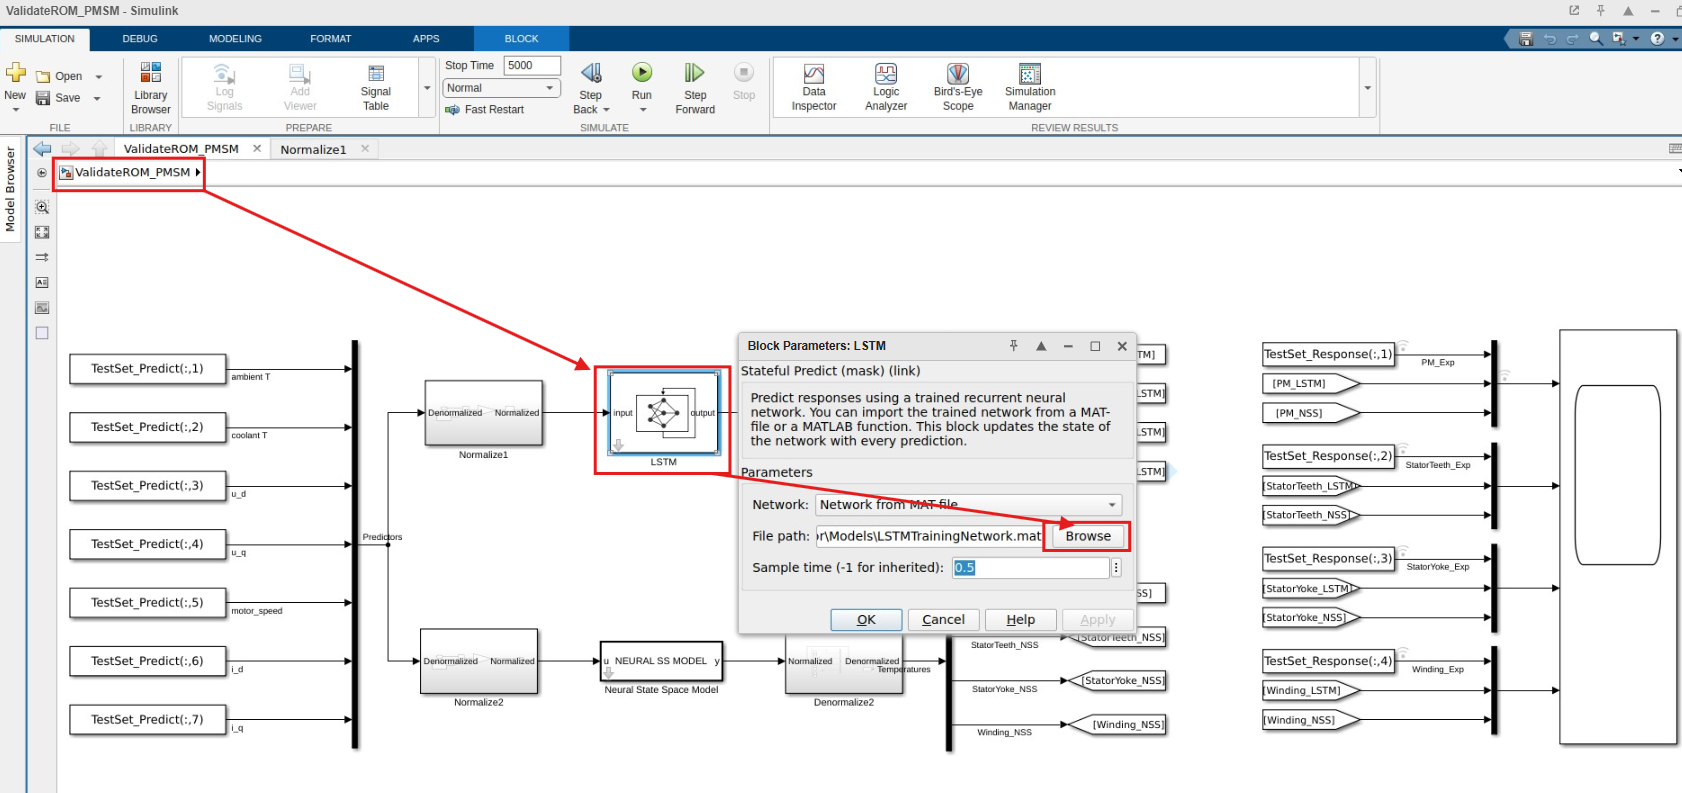

 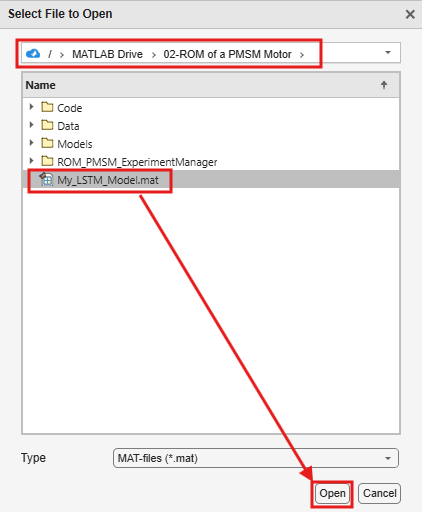

3. Click on OK

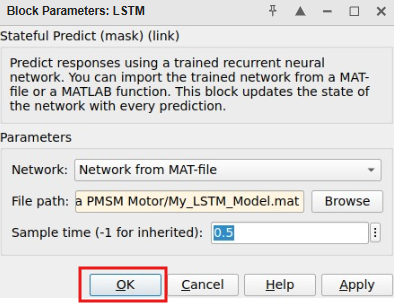

4. Run the following commands to create the normalization and denormalization mean and varianace based on your new model:

Replace "trainingOutput_LSTM_Model" with the name of your exported model

Uncomment the code below if you are using your own trained model exported from experiement manager, if not, the callback function in the Simulink model "ValidateROM_PMSM.slx" loads the existing LSTM network

% exportedMdl = trainingOutput_LSTM_Model;
% 
% % Extract the corresponding input normalizations
% meanX_lstm = exportedMdl.Normalization.Mu{1,1:7};
% stdX_lstm = exportedMdl.Normalization.Sigma{1,1:7};
% 
% 
% % Extract output normalization
% meanY_lstm = exportedMdl.Normalization.Mu{1,8:11};
% stdY_lstm = exportedMdl.Normalization.Sigma{1,8:11};

Run the model. The model scope plots the maximum displacement of the blade from the LSTM model, NSS model, and the high-fidelity model.

% set_param('ValidateROM_PMSM/LSTM','NetworkFilePath',fullfile(cd,'/Models/LSTMTrainingNetwork.mat'));
sim("ValidateROM_PMSM")

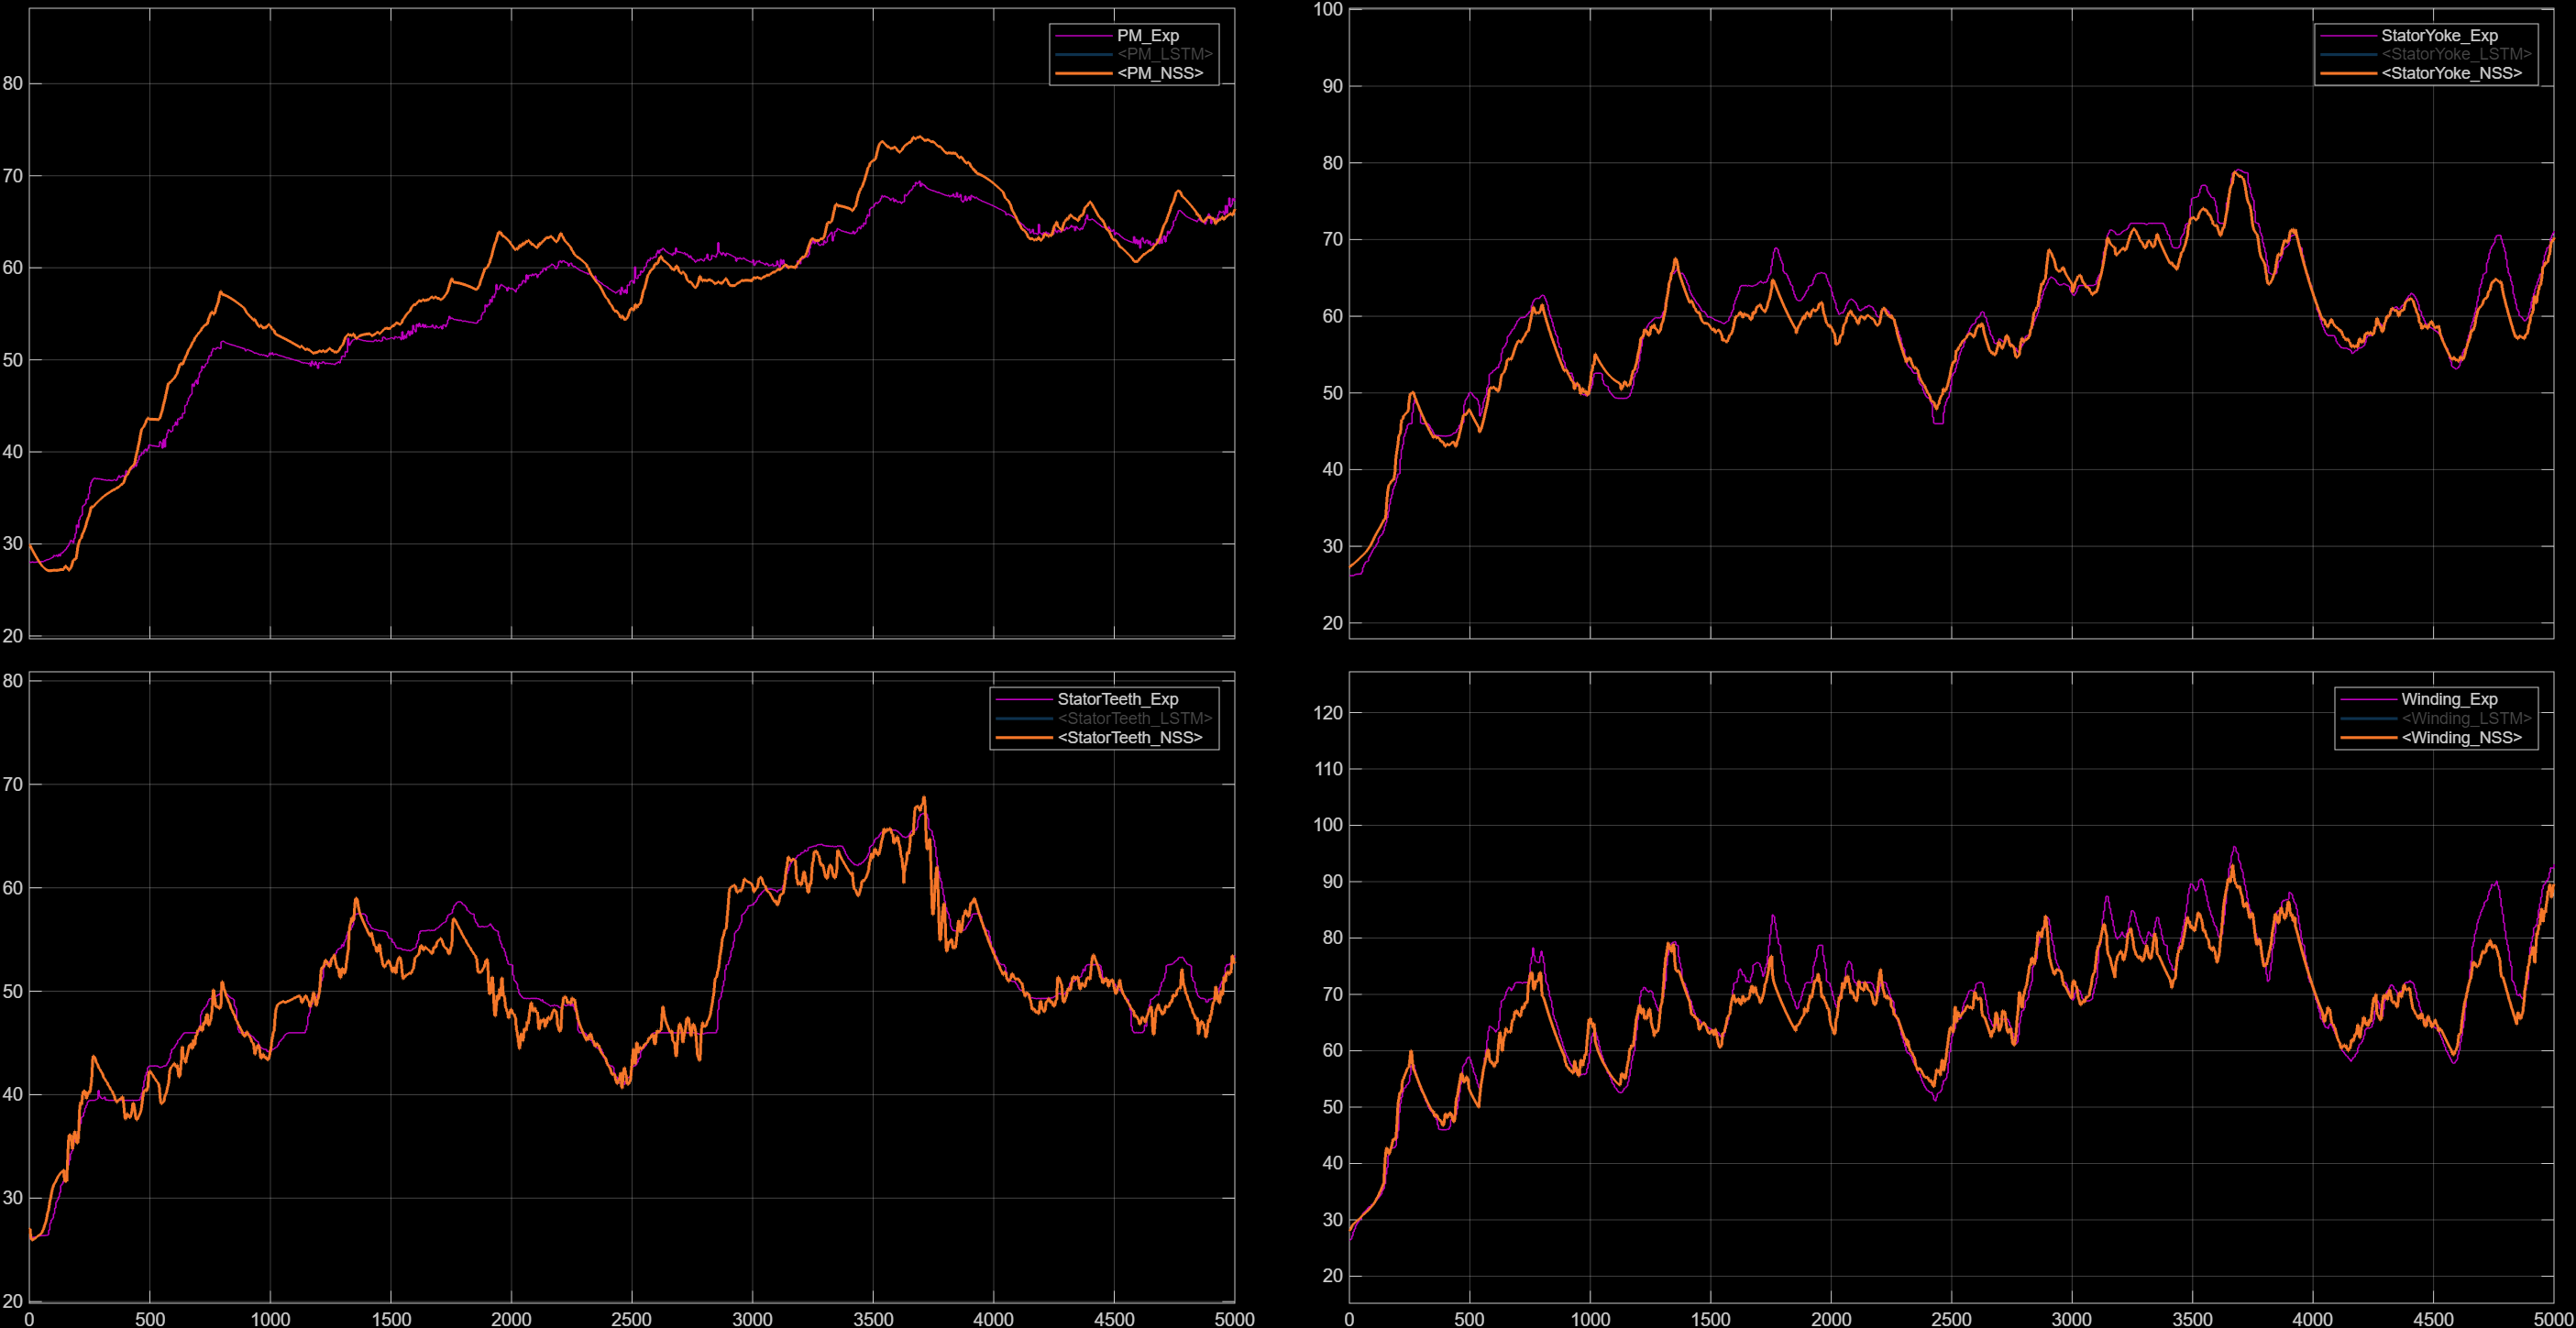

You can see that the trained NSS model is able to generalize reasonably well to this data set compared to LSTM model. To further improve the model, you can:

- Add additional experiments in the Reduced Order Modeler app and use the collected data to retrain the models

- Try different sets of hyperparameters and training options and retrain the models.

Once satisfied with the models, you can use the identified reduced order models in Simulink for hardware-in-the-loop (HIL) testing and control design, or export for use outside of Simulink through FMUs.

(Follow this steps on MATLAB installed on Desktop)

## 8. Code Generation of Reduced order model for HIL testing and embedded deployment

Open Simulink model

slModel = "PMSM_ROM_NSS_CodeGeneration";
load_system(slModel);
open_system(slModel);

Verify Code Generation Settings

cs = getActiveConfigSet(slModel);
openDialog(cs)

If using MATLAB online,select the GCC toolchain for code generation located in the following section: Code Generation -> Build Process -> Toolchain  -> GNU gcc/g++ | gmake 

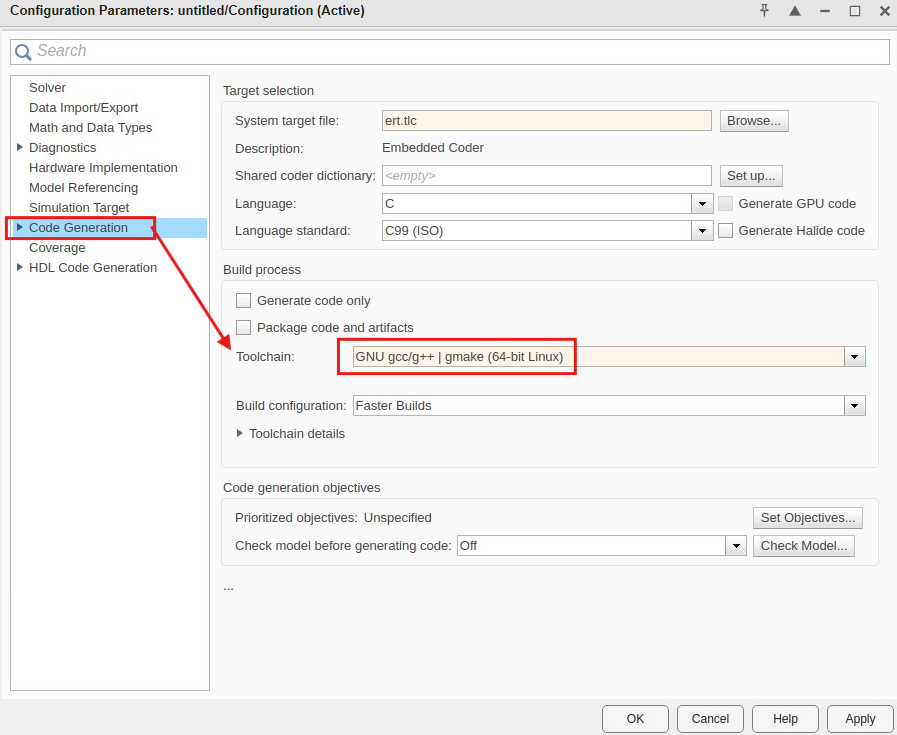

For Hardware-in-the-loop testing, you will need to modify the configuration parameter and prepare the model. Use this [example](https://www.mathworks.com/help/slrealtime/gs/create-and-run-a-real-time-application.html) for reference.

Generate Code via Embedded Coder app

Use Embedded Coder app from within the apps tab in the Simulink toolstrip to generate code. Alternatively use `slbuild` to generate code programmatically. [Example](https://www.mathworks.com/help/ecoder/ug/generating-code-using-embedded-coder.html)

You can resuse the same model for Hardware-in-the-loop testing.

Clean up environement for next exercise

clc
clear
rmpath(genpath(cd));

Copyright 2025 The MathWorks, Inc.